% Define the number of cities
nCities = 10;

% Generate random locations for the cities
cities = rand(nCities, 2);

% Define the population size
popSize = 100;

% Define the maximum number of generations
maxGenerations = 10000;

% Define the mutation rate
mutationRate = 0.01;

% Initialize the population
population = zeros(popSize, nCities);
for i = 1:popSize
    population(i, :) = randperm(nCities);
end

% Evaluate the fitness of the initial population
fitness = zeros(popSize, 1);
for i = 1:popSize
    fitness(i) = evaluateFitness(population(i, :), cities);
end

% Keep track of the best solution
bestSolution = zeros(1, nCities);
bestFitness = Inf;

% Run the GA for a maximum of maxGenerations generations
for generation = 1:maxGenerations
    
    % Create a new population
    newPopulation = zeros(popSize, nCities);
    
    % Keep the best solution from the previous generation
    [~, bestIndex] = min(fitness);
    newPopulation(1, :) = population(bestIndex, :);
    
    % Crossover
    for i = 2:popSize
        % Select two parents randomly from the population
        parent1 = population(randi([1, popSize]), :);
        parent2 = population(randi([1, popSize]), :);
        
        % Perform ordered crossover to create a child
        child = orderedCrossover(parent1, parent2);
        
        % Add random mutations to the child
        if rand() < mutationRate
            child = swapMutation(child);
        end
        
        % Add the child to the new population
        newPopulation(i, :) = child;
    end
    
    % Evaluate the fitness of the new population
    newFitness = zeros(popSize, 1);
    for i = 1:popSize
        newFitness(i) = evaluateFitness(newPopulation(i, :), cities);
    end
    
    % Replace the old population with the new population
    population = newPopulation;
    fitness = newFitness;
    
    % Update the best solution
    [currentBestFitness, currentBestIndex] = min(fitness);
    if currentBestFitness < bestFitness
        bestFitness = currentBestFitness;
        bestSolution = population(currentBestIndex, :);
    end
    
    % Print the current best fitness
    fprintf('Generation %d: Best Fitness = %f\n', generation, bestFitness);
end

Generation 1: Best Fitness = 2.787685
Generation 2: Best Fitness = 2.787685
Generation 3: Best Fitness = 2.787685
Generation 4: Best Fitness = 2.787685
Generation 5: Best Fitness = 2.787685
Generation 6: Best Fitness = 2.787685
Generation 7: Best Fitness = 2.787685
Generation 8: Best Fitness = 2.787685
Generation 9: Best Fitness = 2.787685
Generation 10: Best Fitness = 2.787685
Generation 11: Best Fitness = 2.787685
Generation 12: Best Fitness = 2.787685
Generation 13: Best Fitness = 2.787685
Generation 14: Best Fitness = 2.787685
Generation 15: Best Fitness = 2.787685
Generation 16: Best Fitness = 2.787685
Generation 17: Best Fitness = 2.787685
Generation 18: Best Fitness = 2.787685
Generation 19: Best Fitness = 2.787685
Generation 20: Best Fitness = 2.787685
Generation 21: Best Fitness = 2.787685
Generation 22: Best Fitness = 2.787685
Generation 23: Best Fitness = 2.787685
Generation 24: Best Fitness = 2.787685
Generation 25: Best Fitness = 2.787685
Generation 26: Best Fitness = 2.78

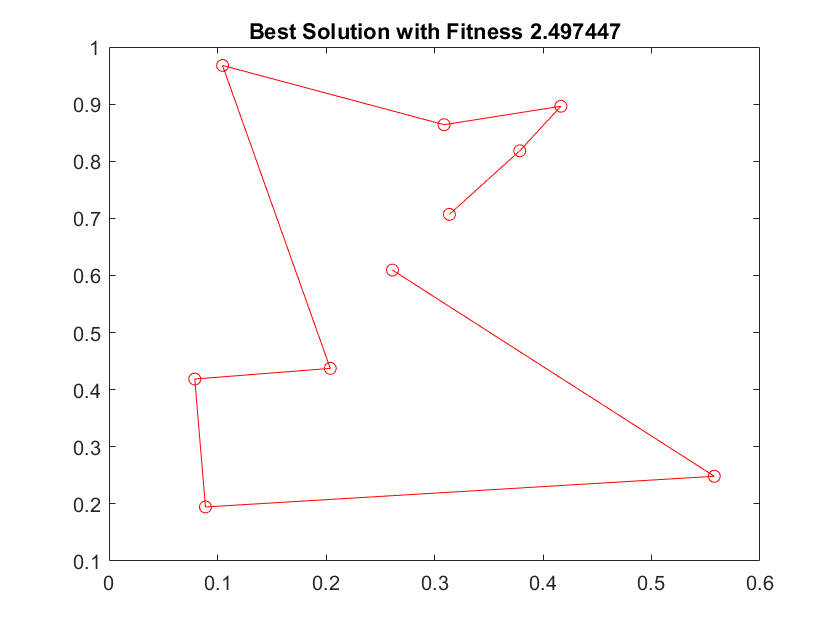


% Plot the best solution
figure;
plot(cities(bestSolution, 1), cities(bestSolution, 2), 'ro-');
title(sprintf('Best Solution with Fitness %f', bestFitness));